# Plot ECE data measured in Razorbill

## Import data

% file = uigetfile
data = importECEmat('20180914_TmAsO4-LS5342-MS180511-IB_EC_vs_T_94p5Hz_-10-180V_compressive_H=10T.txt');

## Separate the data according to the value of Vtot

Vtot = data(:, 8);% equals Vo-Vi (V); negative for compressive, positive for tensile
[uv,~,X] = unique(Vtot);
splitBiasVoltage = accumarray(X,1:size(data,1),[],@(r){data(r,:)});
% https://www.mathworks.com/matlabcentral/answers/345111-splitting-matrix-based-on-a-value-in-one-column

## Split data into heating and cooling runs

k = length(splitBiasVoltage)-1;% do not take into account 0V where there is only 1 data point
for i=1:k
  [rows,columns] = size(splitBiasVoltage{i});%size(splitBiasVoltage{i});  
  [M,I] = min(splitBiasVoltage{i}(:,4));% value and index of temperature minimum
  coolingdata{i}=splitBiasVoltage{i}(1:I,:);% cooling contains data from row 1 to row I (minimum of T)
  heatingdata{i}=splitBiasVoltage{i}(I:rows,:);% heating contains data from row I to the end
end

## Identify columns

for i=1:k
    clg(i).time = coolingdata{i}(:, 1);% time (s)
    clg(i).T_ppms = coolingdata{i}(:, 2);% PPMS(?) temperature (K)
    clg(i).R_lks = coolingdata{i}(:, 3);% ?
    clg(i).T_lks = coolingdata{i}(:, 4);% Sample temperature
    clg(i).B = coolingdata{i}(:, 5);% magnetic field (T)
    clg(i).Vo = coolingdata{i}(:, 6);% outer PZT voltage (V)
    clg(i).Vi = coolingdata{i}(:, 7);% inner PZT voltage (V)
    clg(i).Vtot = coolingdata{i}(:, 8);% equals Vo-Vi (V); negative for compressive, positive for tensile
    clg(i).C = coolingdata{i}(:, 9);% capacitance (pF)
    clg(i).Rece = coolingdata{i}(:,11);% amplitude of the ECE
    clg(i).Phiece = coolingdata{i}(:,12);% phase of the ECE (°)
end

## Plot cooling data

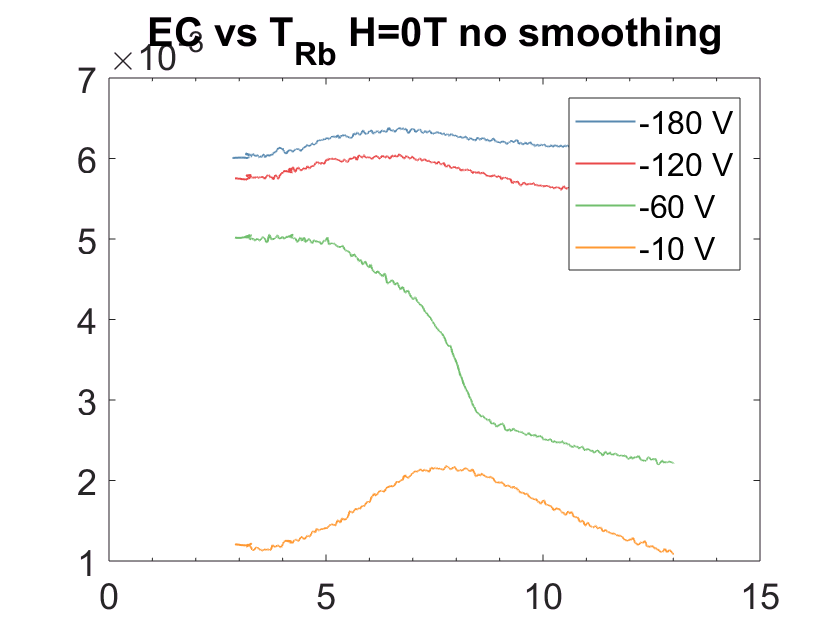

ttl = 'EC vs T_{Rb} H=10T';
figure
C = linspecer(k); 
for i=1:k
   plot(clg(i).T_lks,clg(i).Rece,'color',C(i,:),'linewidth',1); 
   legendInfo{i}=[num2str(uv(i)),' V'];
   hold on
end
title([ttl,' no smoothing'])
legend(legendInfo);

## Smooth data

sgm = 50;% Standard deviation (SD) of the gaussian to convoluate the data with for smoothing
% Reminder: for a gaussian, the full width at half-max is related to the SD by: 
% FWHM = 2*sqrt(2ln(2))*sgm ~ 2.355*sgm
% Given that two consecutive data points are separated by ~1mK in temperature,
% this implies that the smoothing will be made over ~120mK for sgm=50
figure
for i=1:k
   [clg(i).Rece_smth,clg(i).df1,clg(i).df2] = gConvolve(clg(i).Rece,sgm);
   plot(clg(i).T_lks,clg(i).Rece_smth,'color',C(i,:),'linewidth',1); 
%    legendInfo{i}=[num2str(uv(i)),' V'];
   hold on
end
title(['sigma=',num2str(sgm)]);
legend(legendInfo);

## Compute derivative of cooling data

Important note: the cooling data are sorted from high to low temperatures; this implies that diff(clg(i).Rece) computes the opposite of the "derivative" 

figure
for i=1:k
   clg(i).d1 = diff(clg(i).Rece)./diff(clg(i).T_lks);
   plot(clg(i).T_lks(1:end-1),clg(i).d1,'color',C(i,:),'linewidth',1); 
%    legendInfo{i}=[num2str(uv(i)),' V'];
   hold on
end 
title(['Derivative of ', ttl,' no smoothing'])
legend(legendInfo);
ymin = -0.0025;ymax=0.005;
ylim([ymin ymax])

## Smooth derivative of cooling data

Important note: the cooling data are sorted from high to low temperatures; this implies that diff(clg(i).Rece) computes the opposite of the "derivative" 

figure
for i=1:k
   clg(i).d1smth = gConvolve(clg(i).d1,sgm);% becomes infinity if sgm is too high
   plot(clg(i).T_lks(1:end-1),clg(i).d1smth,'color',C(i,:),'linewidth',1); 
   legendInfo{i}=[num2str(uv(i)),' V'];
   hold on
end 
title(['Derivative of ', ttl,' sigma=',num2str(sgm)])
legend(legendInfo);
ylim([ymin ymax])